% Load dataset
T = readtable('diabetes_drug_dataset.csv');

% Encode categorical Drug label
T.Drug = categorical(T.Drug);

% Features (all except Drug)
X = T{:,1:8};  % 8 features
Y = T.Drug;

% Train-test split
cv = cvpartition(height(T),'HoldOut',0.2);
XTrain = X(training(cv), :);
YTrain = Y(training(cv));
XTest = X(test(cv), :);
YTest = Y(test(cv));

% Train Random Forest with OOB importance enabled
model = TreeBagger(100, XTrain, YTrain, ...
    'Method', 'classification', ...
    'OOBPrediction', 'On', ...
    'OOBPredictorImportance','on', ...
    'PredictorNames', T.Properties.VariableNames(1:8));


% Predict
YPred = predict(model, XTest);
YPred = categorical(YPred);

% Accuracy
accuracy = sum(YPred == YTest) / numel(YTest);
disp(['Accuracy: ' num2str(accuracy*100) '%']);

Accuracy: 97%


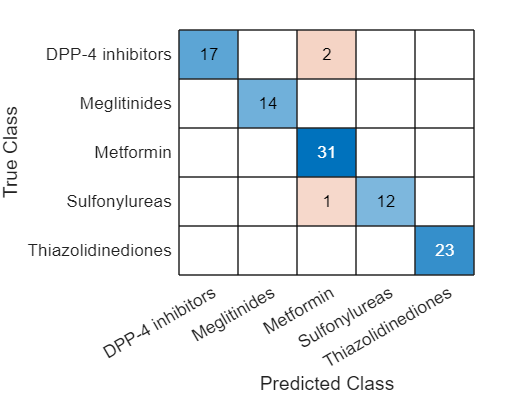


% Confusion matrix
confusionchart(YTest, YPred);

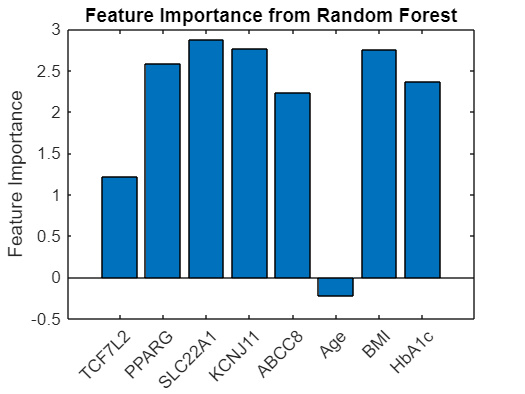


% Feature importance
figure;
bar(model.OOBPermutedPredictorDeltaError);
xticklabels(model.PredictorNames);
xtickangle(45);
ylabel('Feature Importance');
title('Feature Importance from Random Forest');


% New test patient
newPatient = [0.7 0.3 0.2 0.8 0.1 55 28.5 7.2];  % TCF7L2, PPARG, ..., HbA1c
predictedDrug = predict(model, newPatient);
disp(['Predicted drug: ' predictedDrug{1}]);

Predicted drug: Sulfonylureas


% Prompt user for input
disp('Enter patient details:');

Enter patient details:


TCF7L2 = input('TCF7L2 variant score: ');
PPARG = input('PPARG variant score: ');
KCNJ11 = input('KCNJ11 variant score: ');
SLC30A8 = input('SLC30A8 variant score: ');
ABCC8 = input('ABCC8 variant score: ');
Age = input('Age: ');
BMI = input('BMI: ');
HbA1c = input('HbA1c level: ');

% Create input array
newPatient = [TCF7L2, PPARG, KCNJ11, SLC30A8, ABCC8, Age, BMI, HbA1c];

% Predict drug using trained model
predictedDrug = predict(model, newPatient);

% Display result
disp(['Predicted drug: ' predictedDrug{1}]);

Predicted drug: Metformin
